# W8.2 - evolutionary theory

Consider a consumer or predator with a variable trait, teta

### **1) Decide upon the species and the setting**

    Feeding current feeding copepods

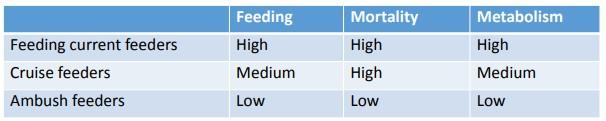

### **2) Write down the trade-off of the trait (costs and benefits)**

    Trait: feeding current speed

    benefits: more food

    costs: higher mortality and metobolism

### **3) Write the population's growth rate as function of the trait, r(teta): **

Defining efficiency function:

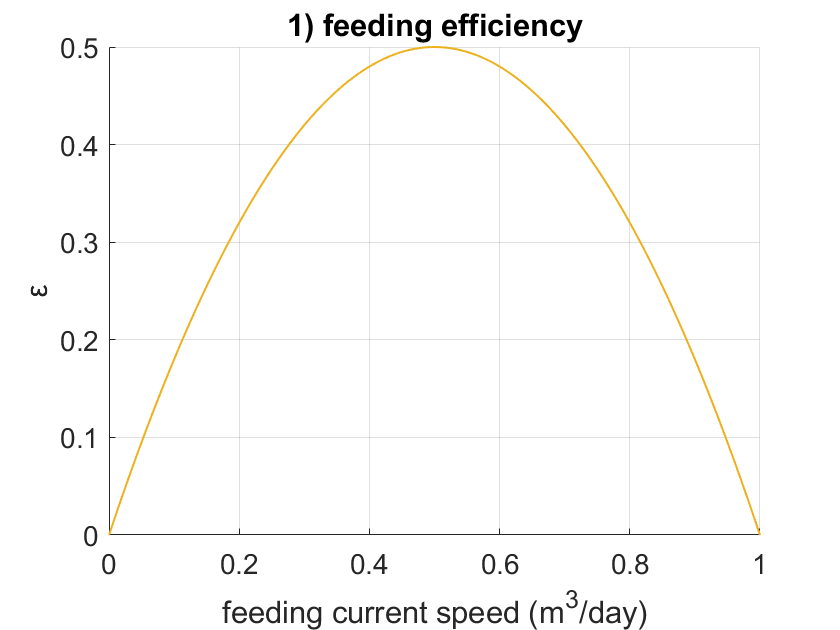

a = -2;       % a<0 parabola branches point down
b_ = 2;       % b>0 top point to the right of y-axis
c = 0;        % y-axis intersection
t = 0:0.01:1;
E = a*t.^2+b_*t+c;  % #N/#R

figure(1) % feeding efficiency
clf
hold on
t = 0:0.01:1;
for i = 1:length(t)
    plot(t,E,'LineWidth',1)
    
grid on
    xlabel('feeding current speed (m^3/day)')
    ylabel('ε')
    title('1) feeding efficiency')
    set(gca,'FontSize', 14)
end

Defining clearance rate function: 

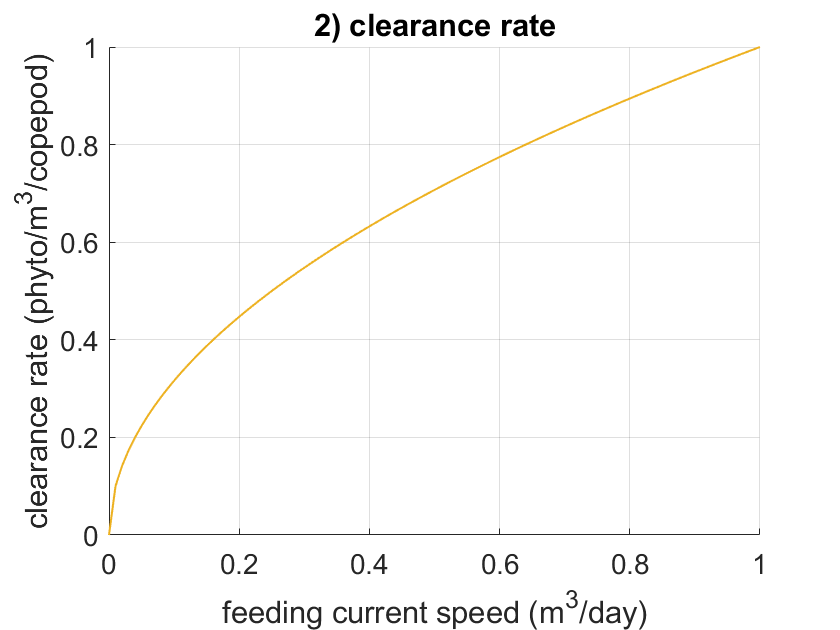

d = 0.5;     % = a
b = t.^d;    % #R/m3/#N

figure(2) % clearance rate
clf
hold on
t = 0:0.01:1;
for i = 1:length(t)
    plot(t,b,'LineWidth',1)
    
grid on
    xlabel('feeding current speed (m^3/day)')
    ylabel('clearance rate (phyto/m^3/copepod)')
    title('2) clearance rate')
    set(gca,'FontSize', 14)
end

Defining metabolic cost function:

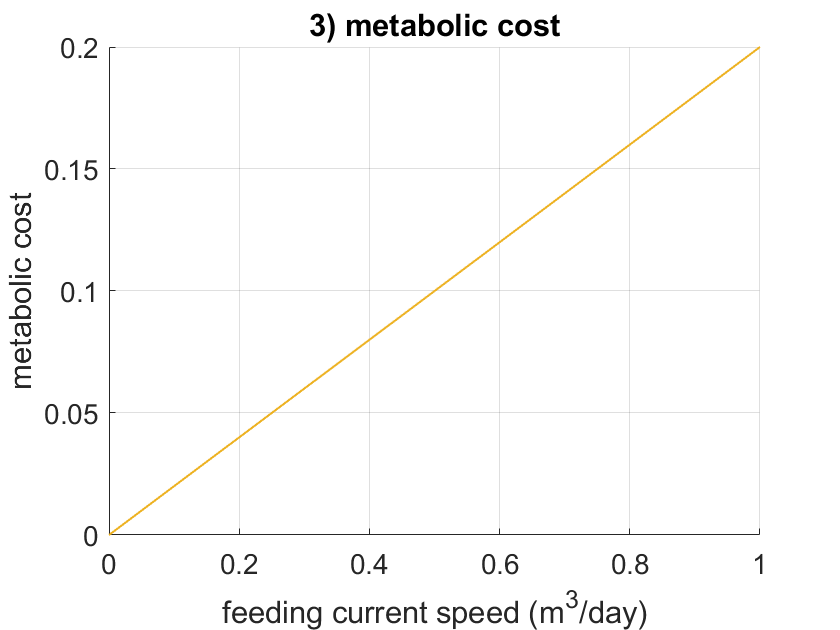

e = 0.2;         % = a slope
f = 0;         % intersection y-axis
M = e*t+f;       % metabolic cost, unit?

figure(3) % metabolic cost
clf
hold on
t = 0:0.01:1;
for i = 1:length(t)
    plot(t,M,'LineWidth',1)
    
grid on
    xlabel('feeding current speed (m^3/day)')
    ylabel('metabolic cost')
    title('3) metabolic cost')
    set(gca,'FontSize', 14)
end

Defining predation mortality function:

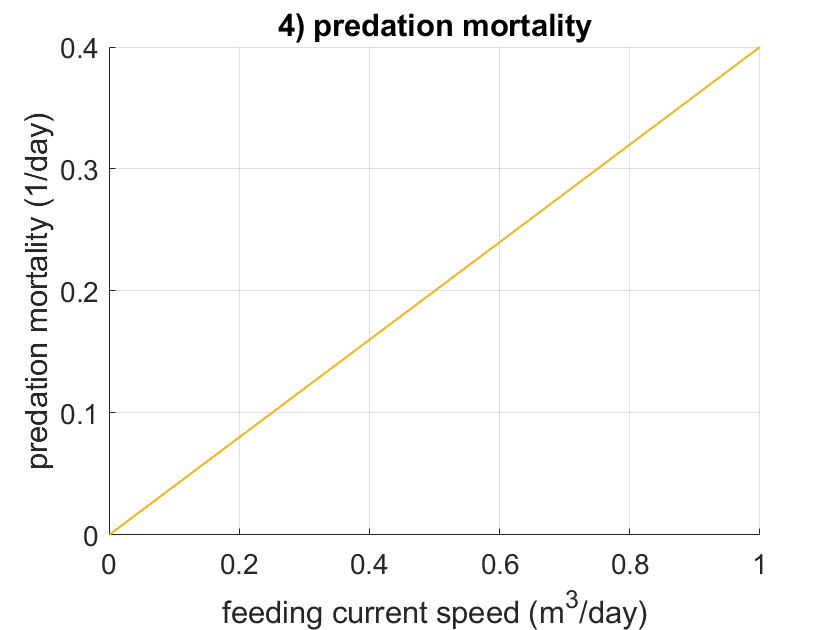

g = 0.4;        % slope
h = 0;        % intersection
mp = g*t+h;     % linear trend (1/day)

figure(4) % predation mortality
clf
hold on
t = 0:0.01:1;
for i = 1:length(t)
    plot(t,mp,'LineWidth',1)
    
grid on
    xlabel('feeding current speed (m^3/day)')
    ylabel('predation mortality (1/day)')
    title('4) predation mortality')
    set(gca,'FontSize', 14)
end

Mortality parameters:

m0 = 0.6;       % 1/day
m = m0 - mp;    % 1/day

Remaining parameters:

    t = teta (trait)

R = 500;    % #phytoplankton/m3
Cmax = 100; % #R/day

The population's growth rate as function of the trait, r(teta):

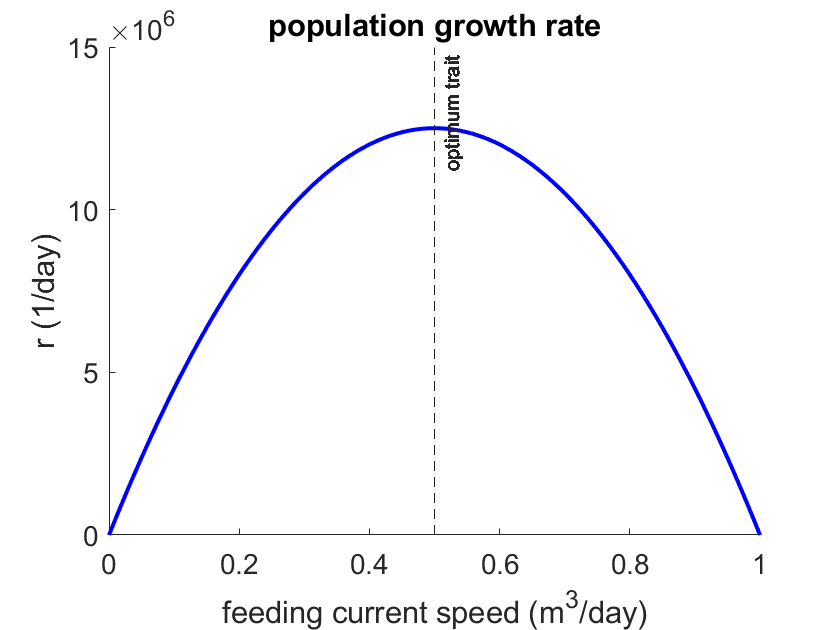

r = E.*(Cmax*((b*R)/b*R+Cmax)-M)-m;


figure(5) % population growth rate with increasing feeding current speed
clf
hold on
t = 0:0.01:1;
for i = 1:length(t)
    plot(t,r,'b','LineWidth',2)
    xline(0.500,'--', 'optimum trait')
    xlabel('feeding current speed (m^3/day)')
    ylabel('r (1/day)')
    title('population growth rate')
    set(gca,'FontSize', 14)
end